c = readtable("clean_data/image_cts.csv")

c = 2244×1 table
    id
    __

    1 
    1 
    1 
    1 
    1 
    1 
    1 
    1 
    1 
    1 
    1 
    1 
    2 
    2 
    2 
    2 


t = readtable("clean_data/labels.csv")

t = 267×47 table
    ID               NewName                            Name                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        

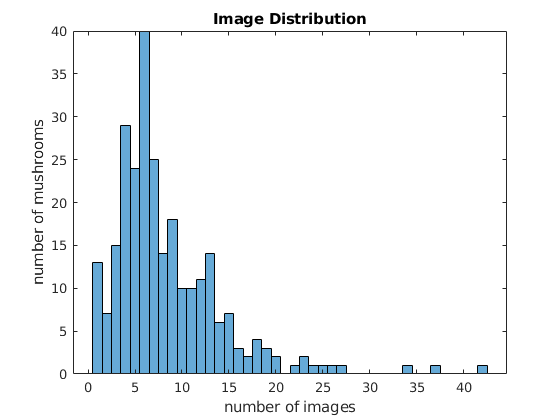


h = histcounts(c.id, length(unique(c.id)));
[counts, idx] = sort(h);
histogram(counts)
xlabel("number of images")
ylabel("number of mushrooms")
title("Image Distribution")


writetable(t(h < 6, ["ID","NewName", "Name"]), "clean_data/lowest_image_counts.csv")

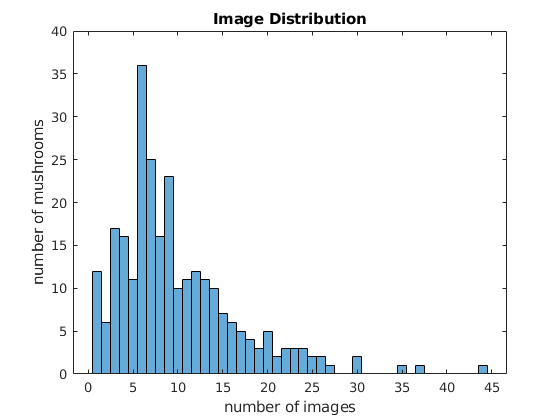

c = readtable("clean_data/image_ids.csv");
t = readtable("clean_data/labels.csv");

h = histcounts(c.id, length(unique(c.id)));
[counts, idx] = sort(h);
histogram(counts)
xlabel("number of images")
ylabel("number of mushrooms")
title("Image Distribution")


writetable(t(h < 6, ["ID","NewName", "Name"]), "clean_data/lowest_image_counts_new.csv")